% parameters; only examining slice 11
clc; clear;
slice = 11;
num_slices = 24;
num_angles = 90;
slice_bins = 350;
min_bin = (slice-1)*num_angles*slice_bins;
max_bin = slice*num_angles*slice_bins-1;

% load history information
file = '/Users/cflin/Downloads/history_info_badEx.bin';
fid = fopen(file,'rb','ieee-le');
n = fread(fid,1,'int32');
bin_num_vector = fread(fid, n, 'int32');
WEPL_fbp = fread(fid, n, 'single');
x_entry_vector = fread(fid, n, 'single');
y_entry_vector = fread(fid, n, 'single');
z_entry_vector = fread(fid, n, 'single');
x_exit_vector = fread(fid, n, 'single');
y_exit_vector = fread(fid, n, 'single');
z_exit_vector = fread(fid, n, 'single');
xy_entry_angle_vector = fread(fid, n, 'single');
xz_entry_angle_vector = fread(fid, n, 'single');
xy_exit_angle_vector = fread(fid, n, 'single');
xz_exit_angle_vector = fread(fid, n, 'single');
fclose(fid);

% restrict to only those histories with bins corresponding to slice
slice_restrict = (bin_num_vector>=min_bin) & (bin_num_vector<=max_bin);

bin_num_vector = bin_num_vector(slice_restrict);
WEPL_fbp = WEPL_fbp(slice_restrict);
x_entry_vector = x_entry_vector(slice_restrict);
y_entry_vector = y_entry_vector(slice_restrict);
z_entry_vector = z_entry_vector(slice_restrict);
x_exit_vector = x_exit_vector(slice_restrict);
y_exit_vector = y_exit_vector(slice_restrict);
z_exit_vector = z_exit_vector(slice_restrict);
xy_entry_angle_vector = xy_entry_angle_vector(slice_restrict);
xz_entry_angle_vector = xz_entry_angle_vector(slice_restrict);
xy_exit_angle_vector = xy_exit_angle_vector(slice_restrict);
xz_exit_angle_vector = xz_exit_angle_vector(slice_restrict);

% restricting histories to only those that are binned to our slice
full_data = [bin_num_vector, WEPL_fbp, x_entry_vector, y_entry_vector, ...
                z_entry_vector, x_exit_vector, y_exit_vector, z_exit_vector, ...
                xy_entry_angle_vector, xz_entry_angle_vector, ...
                xy_exit_angle_vector, xz_exit_angle_vector];
% looking at number of unique bin_num_vector values, 
%   get correct 160*90 amount

% load sinogram, corresponding counts
file = '/Users/cflin/Downloads/sinogram_badEx.txt';
[sino, sino_slice] = read_pct_sinogram(file, 0, 0, num_angles, slice); 
file_name = '/Users/cflin/Downloads/bin_counts_post_badEx.txt';
bin_counts = readmatrix(file_name);

negative_bins = []; 
neg_sino_values = [];
neg_bin_counts = [];
for kk = (slice-1)*num_angles+1:num_angles*slice
    for jj = 1:size(sino,2)
        if sino(kk,jj)<0
            b = (kk-1)*350 + jj - 1;
            negative_bins = [negative_bins, b];
            neg_sino_values = [neg_sino_values, sino(kk,jj)];
            neg_bin_counts = [neg_bin_counts, bin_counts(kk,jj)];
        end
    end
end

% figure; imagesc(sino_slice);
% title('Sinogram for Middle Slice' ,'FontSize',16);

% restrict histories to only those with a negative sinogram value
% min of 326030, max of 343887 -> 24828 histories remaining
neg_bin_hists = full_data(ismember(full_data(:,1),negative_bins),:);

% what happens if we restrict to valid histories?
sub1 = neg_bin_hists(neg_bin_hists(:,2) >= -20,:); % 17897 remaining

% look only at histories with bin value: 326030
hist326030 = full_data(full_data(:,1) == 326030,:); 
disp([mean(hist326030(:,2)), neg_sino_values(1), size(hist326030,1), neg_bin_counts(1)])

   -6.1496   -6.1496  244.0000  244.0000



% this corresponds to the 244 in bin_counts
sub1_326030 = sub1(sub1(:,1)==326030,:); %194 remaining; 50 registering as "-100"
disp(size(sub1_326030))

   194    12



disp(mean(sub1_326030(:,2))  )

   18.0386



%doing only mean of the histories that should be valid, get 18.0
%   much more reasonable

% restrict histories to only those with a negative sinogram value, more
% than -10
thisBin = 326031;
hist326031 = full_data(full_data(:,1) == thisBin,:); 
disp(size(hist326031))

   263    12



% 263 remaining

file_name = '/Users/cflin/Downloads/x_1_corrected.txt';
corrected_full = readmatrix(file_name);
N = size(corrected_full,2);
corrected_full_slice = corrected_full((slice-1)*N+1:slice*N,:);


% visualize
% check the angles: this displays all the histories
% want to overlay this onto scan; need to recenter the coordinates to do
% so in addition to loading in image: 0,0 -> N/2, N/2

figure; tiledlayout(1,2); 
nexttile(1); 
imshow(corrected_full_slice./max(corrected_full_slice(:)), ...
       'InitialMagnification','fit');

Unrecognized function or variable 'corrected_full_slice'.

nexttile(2);
imshow(corrected_full_slice./max(corrected_full_slice(:)), ...
       'InitialMagnification','fit');
hold on;
negBinHist = neg_bin_hists(neg_bin_hists(:,2)<-20,:);
for ii = 1:size(negBinHist,1)
        xs = [negBinHist(ii,3), negBinHist(ii,6)]./0.0625+N/2;  
        ys = -[negBinHist(ii,4), negBinHist(ii,7)]./0.0625+N/2;
        plot(xs, ys);
end
hold off;

% look at total counts for these:


% looking only at histories with wepl -100:
mdata100 = full_data(full_data(:,2)==-100,:);
figure; hold on;
for ii = 1:size(mdata100,1)
    plot([mdata100(ii,3), mdata100(ii,6)], [mdata100(ii,4), mdata100(ii,7)]);
end
hold off;

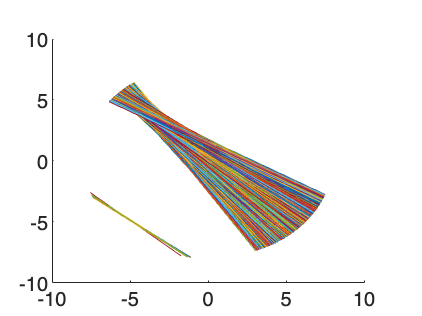

file = '/Users/cflin/Downloads/sinogram_corrected.txt';
[sino_corr, sino_slice_corr] = read_pct_sinogram(file, 0, 0, num_angles*4, slice); 
figure; imagesc(sino_slice)

return;
% loading 
file_name = '/Users/cflin/Downloads/OddHistories_Metadata.txt';
metadata = readmatrix(file_name);
figure; hold on;
for ii = 1:100%size(metadata,1)
    plot([metadata(ii,4), metadata(ii,7)], [metadata(ii,5), metadata(ii,8)]);
end
hold off;
% WEPL_vector (1), bin_num_vector (2), gantry_angle_orig (3), x_entry_vector (4), 
%     y_entry_vector (5), z_entry_vector (6), x_exit_vector (7), y_exit_vector (8), z_exit_vector (9),
%     xy_entry_angle_vector (10), xz_entry_angle_vector (11), xy_exit_angle_vector (12), 
%     xz_exit_angle_vector (13) , rel_ut_angle_vector (14), rel_uv_angle_vector (15)
ang = 48;
tmp = metadata(metadata(:,3) == ang,:);
figure; hold on;

for ii = 1:size(tmp,1)
    plot([tmp(ii,4), tmp(ii,7)], [tmp(ii,5), tmp(ii,8)]);
end
hold off;

neg_bins = []; 


neg_histories = metadata(ismember(metadata(:,2), negative_bins),:);
figure; hold on;
for ii = 1:size(neg_histories)
    if neg_histories(ii,1)>=-20
    plot([neg_histories(ii,4), neg_histories(ii,7)], [neg_histories(ii,5), neg_histories(ii,8)]);
    disp([neg_histories(ii,1), neg_histories(ii,2), neg_histories(ii,3)]); %display wepl, bin number, gantry
    end
end
hold off;

file_name = '/Users/cflin/Downloads/bin_counts_post.txt';
bin_counts = readmatrix(file_name);
bin_ct_slice = bin_counts((slice-1)*num_angles+1:slice*num_angles,:);
negative_bins = []; %keep slice 1-15
neg_sino_values = [];
neg_sinbin_counts = [];
for kk = 10*90+1:90*11%size(sino,1)
    for jj = 1:size(sino,2)
        if sino(kk,jj)<0
            b = (kk-1)*350 + jj - 1;
            negative_bins = [negative_bins, b];
            neg_sino_values = [neg_sino_values, sino(kk,jj)];
            neg_sinbin_counts = [neg_sinbin_counts, bin_counts(kk,jj)];
        end
    end
end